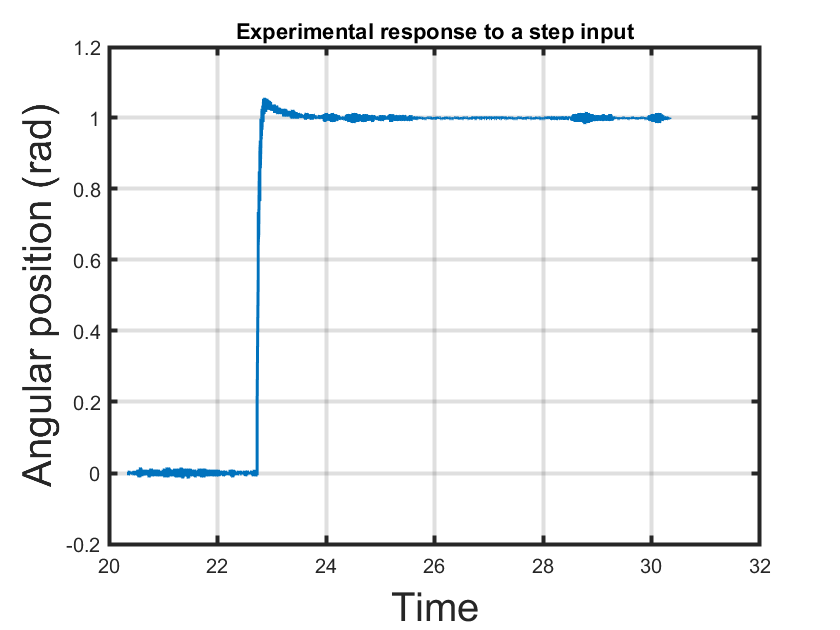

clear;
close all;

[overshoot] = xlsread("overshoot.xlsx");

cola = overshoot(1:end, 1);
colb = overshoot(1:end, 2);
colc = linspace(1,1,length(cola));

figure(1);box on; hold on;
plot(cola,colb,'LineWidth',1.5);
% plot(cola,colc,'LineWidth',1.5);
ylabel('Angular position (rad)',"FontSize",20);
xlabel('Time','FontSize',20)
title("Experimental response to a step input")
grid on;
set(gca,'linewidth',2)

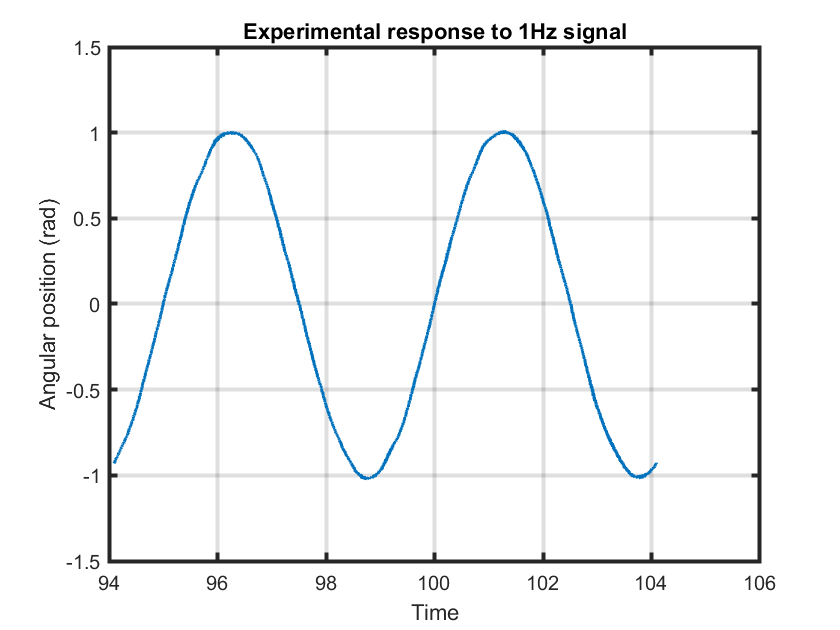



[one] = xlsread("position_1Hz.xlsx");

cola = one(1:end, 1);
colb = one(1:end, 2);

figure(2);box on;
plot(cola,colb,'LineWidth',1.5);
ylabel('Angular position (rad)');
xlabel('Time')
title("Experimental response to 1Hz signal")
grid on;
set(gca,'linewidth',2)


[three] = xlsread("position_3Hz.xlsx");

cola = three(1:end, 1);
colb = three(1:end, 2);

figure(2);box on;

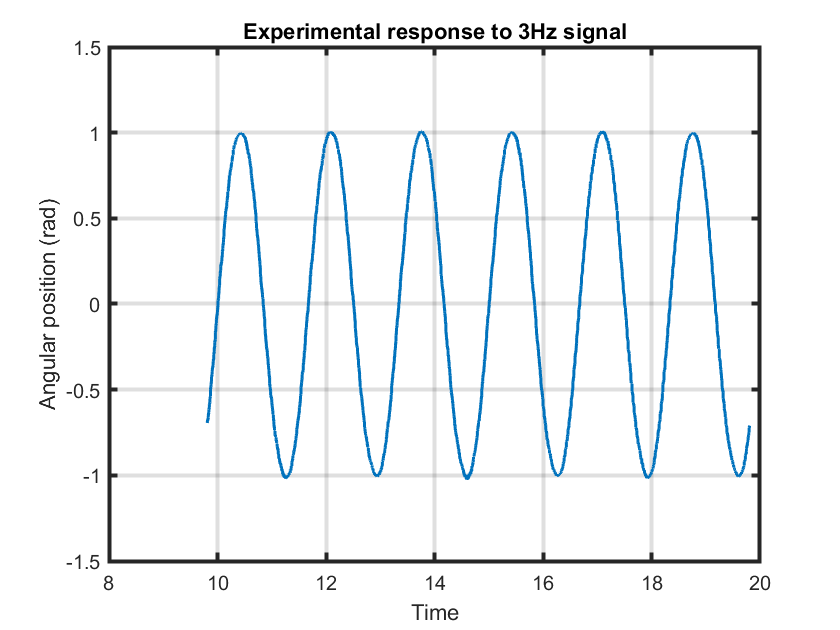

plot(cola,colb,'LineWidth',1.5);
ylabel('Angular position (rad)');
xlabel('Time')
title("Experimental response to 3Hz signal")
grid on;
set(gca,'linewidth',2)


[five] = xlsread("position_3Hz.xlsx");

cola = five(1:end, 1);
colb = five(1:end, 2);

figure(2);box on;

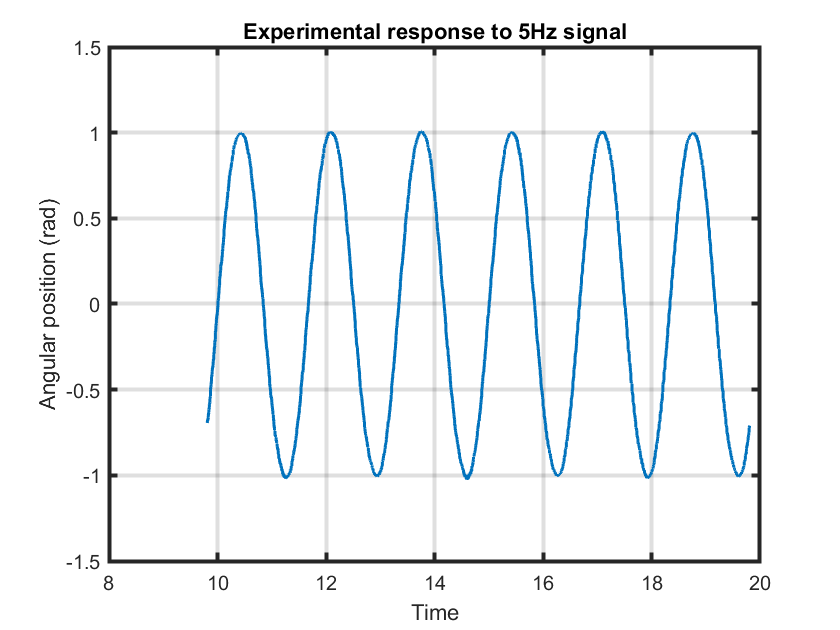

plot(cola,colb,'LineWidth',1.5);
ylabel('Angular position (rad)');
xlabel('Time')
title("Experimental response to 5Hz signal")
grid on;
set(gca,'linewidth',2)

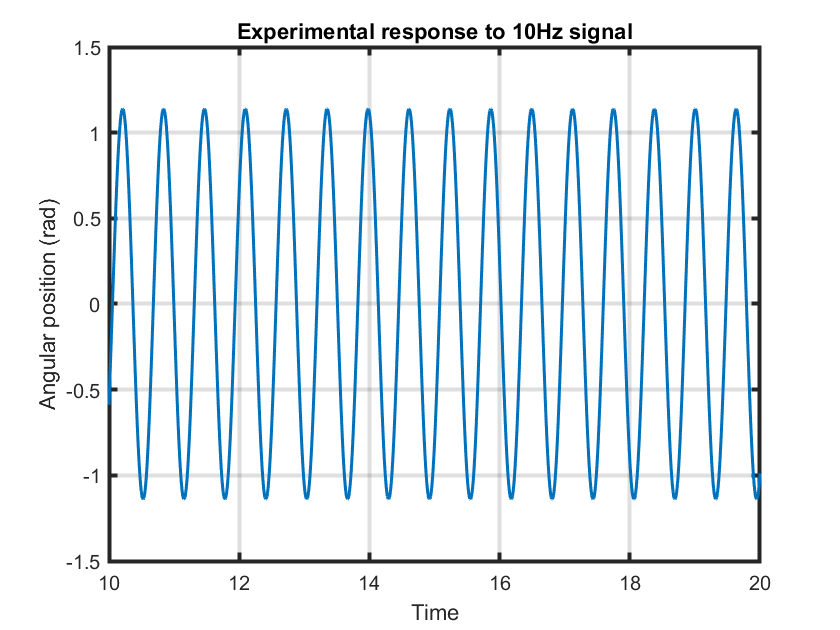


t = linspace(1,100,10000);
y1 = 1.14*sin(10*t);

figure(3);box on;
plot(t,y1,'LineWidth',1.5);
ylabel('Angular position (rad)');
xlabel('Time')
title("Experimental response to 10Hz signal")
grid on;
xlim([10 20])
set(gca,'linewidth',2)


y2 = 0.98*sin(15*t)

y2 =     0.6373    0.5201    0.3915    0.2542    0.1114   -0.0339   -0.1785   -0.3191   -0.4527   -0.5763   -0.6873   -0.7831   -0.8616   -0.9212   -0.9606   -0.9787   -0.9753   -0.9505   -0.9047   -0.8390   -0.7549   -0.6541   -0.5389   -0.4118   -0.2757   -0.1335    0.0116    0.1565    0.2979    0.4328    0.5581    0.6712    0.7694    0.8508    0.9134    0.9559    0.9773    0.9773    0.9557    0.9131    0.8503    0.7689    0.6705    0.5574    0.4320    0.2971    0.1556    0.0107   -0.1344   -0.2765



figure(4);box on;
plot(t,y2,'LineWidth',1.5);
ylabel('Angular position (rad)');
xlabel('Time')
title("Experimental response to 15Hz signal")
grid on;
xlim([10 20])
set(gca,'linewidth',2)

y3 = 0.7*sin(20*t)

y3 =     0.6391    0.6828    0.6998    0.6895    0.6522    0.5894    0.5036    0.3981    0.2771    0.1452    0.0077   -0.1302   -0.2629   -0.3854   -0.4929   -0.5810   -0.6465   -0.6867   -0.7000   -0.6860   -0.6452   -0.5791   -0.4905   -0.3826   -0.2598   -0.1269    0.0110    0.1485    0.2802    0.4009    0.5060    0.5912    0.6534    0.6900    0.6997    0.6820    0.6377    0.5684    0.4769    0.3668    0.2424    0.1084   -0.0297   -0.1667   -0.2972   -0.4161   -0.5187   -0.6010   -0.6599   -0.6929


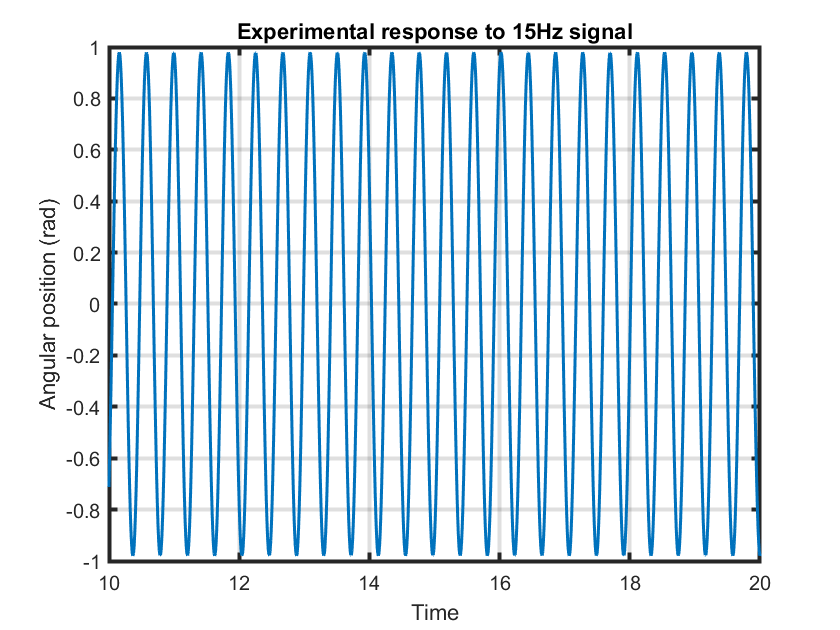


figure(4);box on;

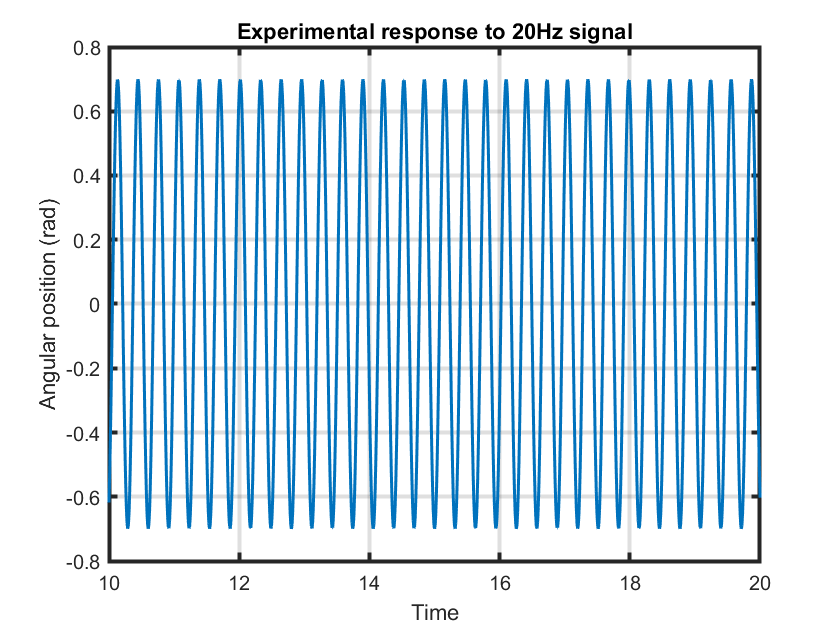

plot(t,y3,'LineWidth',1.5);
ylabel('Angular position (rad)');
xlabel('Time')
title("Experimental response to 20Hz signal")
grid on;
xlim([10 20])
set(gca,'linewidth',2)

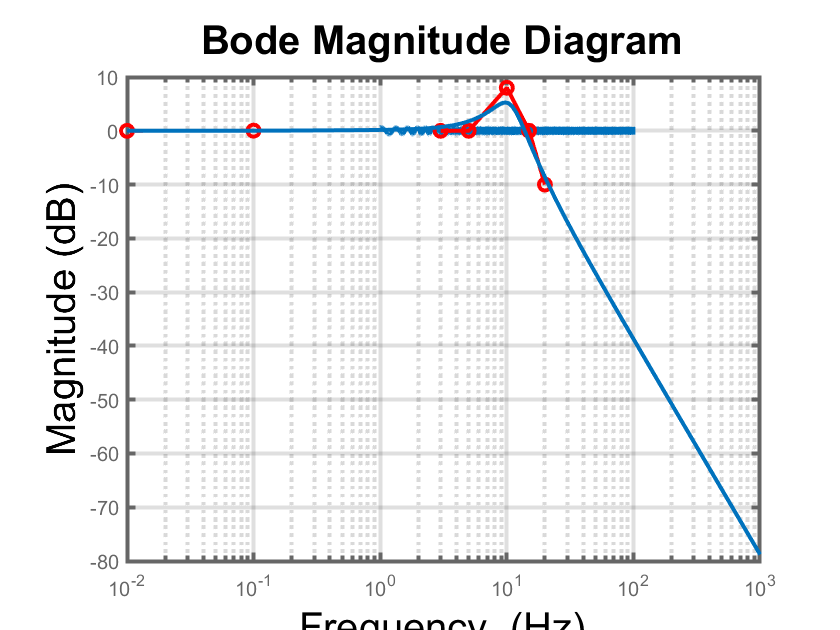

V = [0.25 0.5 0.75];
i_monitor = [0.23 0.47 0.72];
i_probe = [0.233 0.464 0.701];
i_avg = (i_monitor + i_probe) / 2;
K_a = mean(i_avg ./ V);

% Motor Properties
K_t = 4.24e-2; % Nm/A
J = 8.5e-6; %Kg-m^2
b = 3.7e-6; % Nm-s damping constant
G_s = tf([K_t*K_a],[J,b,0]);


K = 0.975;
z1 = 0.2739;
p1 = 0.1011;
z2 = 1.6;
p2 = 40;
C = K*tf([1 z1],[1 p1])*tf([1 z2],[1 p2]);
h = feedback(C*G_s,1);

fr = [.01,0.1,-1,3,5,10,15,20];
value = [-0.01,0.02,0.01,-0.01,0,8,0,-10];

figure(4);  grid on; box on; hold on;
set(gca,'linewidth',2)
plot(fr,value,'-ro')
G = bodeplot(h);
setoptions(G,'FreqUnits','Hz','PhaseVisible','off','Grid','on');
ylabel('Phase','FontSize',20)
xlabel('Frequency','FontSize',20)
title('Bode Magnitude Diagram','FontSize',20)
set(findall(gcf,'type','line'),'Linewidth',2);

set(gca,'linewidth',2)

